%https://www.mathworks.com/help/supportpkg/plutoradio/ug/channel-io.html

% Setup Spectrum viewer
spectrumScope = spectrumAnalyzer( ...
    SpectrumType='power-density', ...
    Title='Received Signal Spectrum', ...
    YLabel='Power spectral density', ...
    Position=[69 376 800 450]);


sdrReceiver  = sdrrx('Pluto');
fs = 10e6;
fc = 2.4e9; %2.415e9;
sdrReceiver.BasebandSampleRate = fs;
sdrReceiver.CenterFrequency = fc;
sdrReceiver.OutputDataType = 'double';
sdrReceiver.GainSource = 'Manual';
sdrReceiver.Gain = 10;
%sdrReceiver.ShowAdvancedProperties = true;
%sdrReceiver.BypassUserLogic = true;

sdrReceiver.SamplesPerFrame = 4096 %2*length(txWaveform);

sdrReceiver =   comm.SDRRxPluto with properties:

   Main
                DeviceName: 'Pluto'
                   RadioID: 'usb:0'
           CenterFrequency: 2.400000000000000e+09
                GainSource: 'Manual'
                      Gain: 10
            ChannelMapping: 1
        BasebandSampleRate: 10000000
            OutputDataType: 'double'
           SamplesPerFrame: 4096
           EnableBurstMode: false
    ShowAdvancedProperties: false

  Show all properties


fprintf('\nStarting a new RF capture.\n')


Starting a new RF capture.





osf = 2 %oversamplingrate

osf =      2


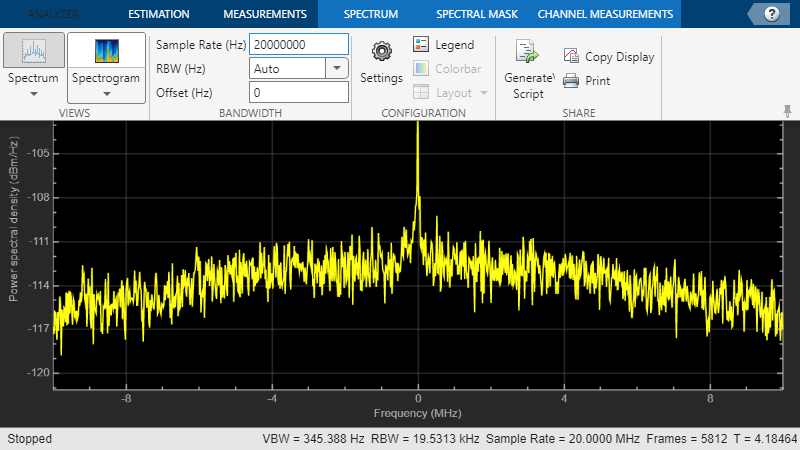

spectrumScope.SampleRate = fs*osf;

%rxWaveform = capture(sdrReceiver,sdrReceiver.SamplesPerFrame,'Samples');
%data = rx();
%spectrumScope(rxWaveform);

tic
while toc < 30
    rxWaveform = plutoRx();
    spectrumScope(rxWaveform);
end


release(spectrumScope);

release(sdrReceiver);

